
img1=imread('C:\Users\Notebook\Desktop/wallpaper/house.jpg');
size(img1)

ans =    170   296     3


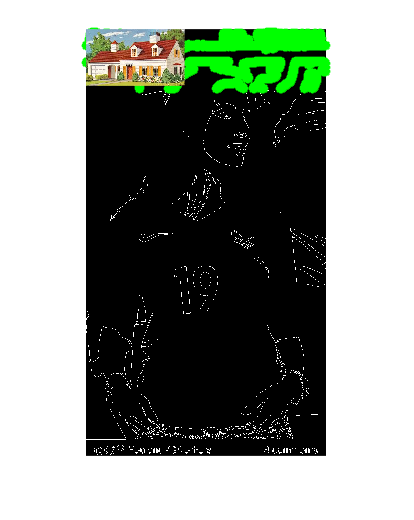

imshow(img1);

Retrieve the Red, Green and Blue Component.

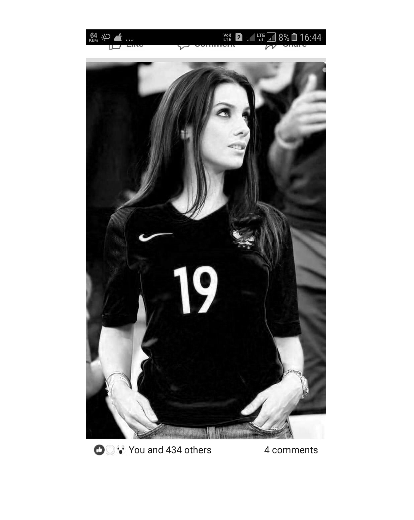

rc=img1(:,:,1);
imshow(rc);

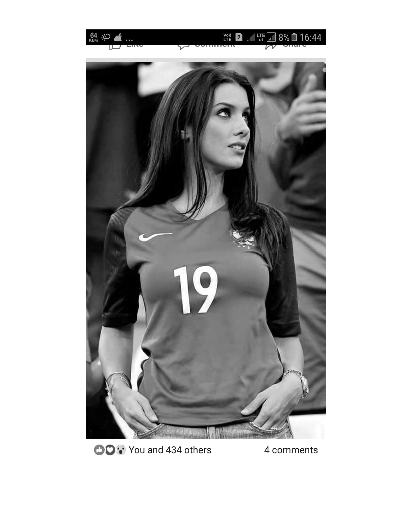

gc=img1(:,:,2);
imshow(gc);

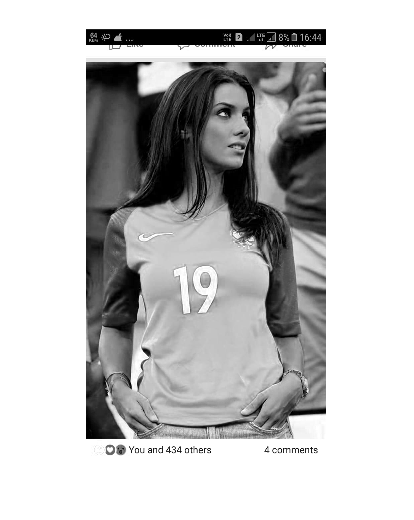

bc=img1(:,:,3);
imshow(bc);

Converting RGB image to Gray image

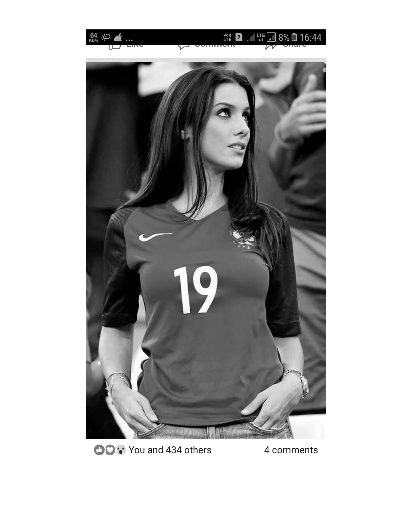

img2=rgb2gray(img1);
imshow(img2);

Finding the threshold level of Gray image.

level=graythresh(img2)

level = 0.5216

Converting image to digital image

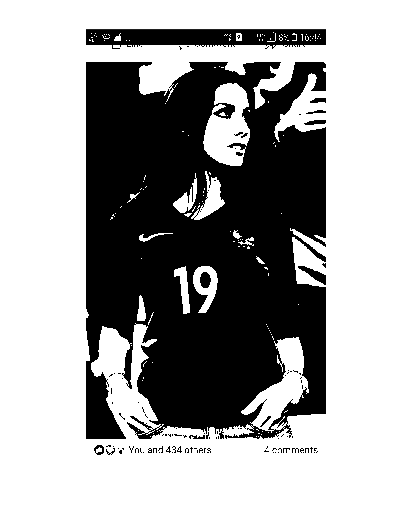

img3=im2bw(img2,level);
imshow(img3);

Detecting edge of an image.

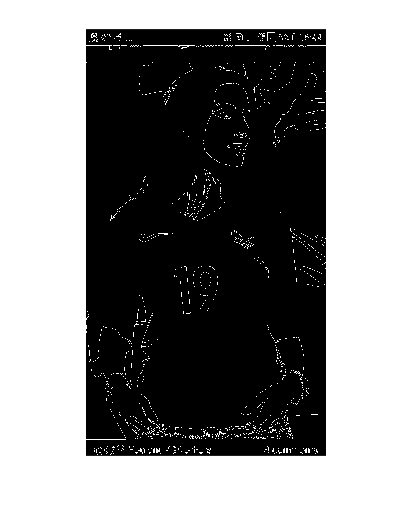

e=edge(img3);
array=[];
for i=1:1:1280
    for j=1:1:720
        if(e(i,j)==1)
            array2=[i,j];
            array=vertcat(array,array2);
        end
    end
end
imshow(e);

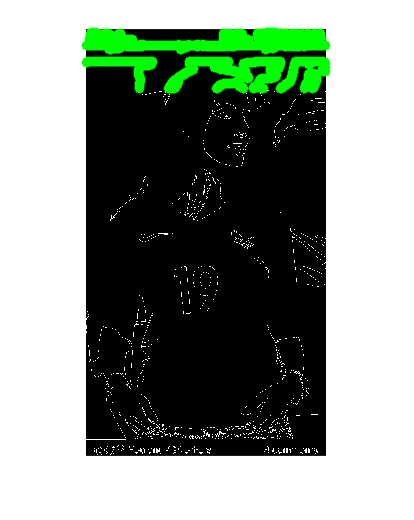

hold on
s=size(array);
for i=1:1:s(1)
    plot(array(i,2),array(i,1),'*g','linewidth',5);
    pause(0.001);
end